# HW2

% path = 'ErrPSpeller\Subject1\Offline';
% for mac
path = 'ErrPSpeller/Subject1/Offline';
[signals, event] = loadData(path);

Hint: the performance of SLOAD can be improved with mexSLOAD.mex which is part of biosig4c++.
Warning SOPEN: number of event onset (TYP=4F6) and event offset (TYP=84F6) differ
Warning SOPEN: number of event onset (TYP=1CB5) and event offset (TYP=9CB5) differ
Warning SOPEN: number of event onset (TYP=2A71) and event offset (TYP=AA71) differ
Warning SOPEN: number of event onset (TYP=2A8E) and event offset (TYP=AA8E) differ
Warning SOPEN: number of event onset (TYP=3363) and event offset (TYP=B363) differ
Warning SOPEN: number of event onset (TYP=3580) and event offset (TYP=B580) differ
Warning SOPEN: number of event onset (TYP=37C7) and event offset (TYP=B7C7) differ
Warning SOPEN: number of event onset (TYP=7877) and event offset (TYP=F877) differ
Warning SOPEN: number of event onset (TYP=7BA1) and event offset (TYP=FBA1) differ
Warning SOPEN: number of event onset (TYP=16EE) and event offset (TYP=96EE) differ
Warning SOPEN: number of event onset (TYP=2C27) and event offset (TYP=AC27) d

% [signal,H] = sload('ad4_raser_offline_offline_171110_170617.gdf');
signals = signals(:, 1:16);
fs = 512;
load chanlocs16.mat chanlocs16
%% Fz, FC3, FC1, FCz, FC2, FC4, C3, C1, Cz, C2, C4, CP3, CP1, CPz, CP2, CP4

## Filtering

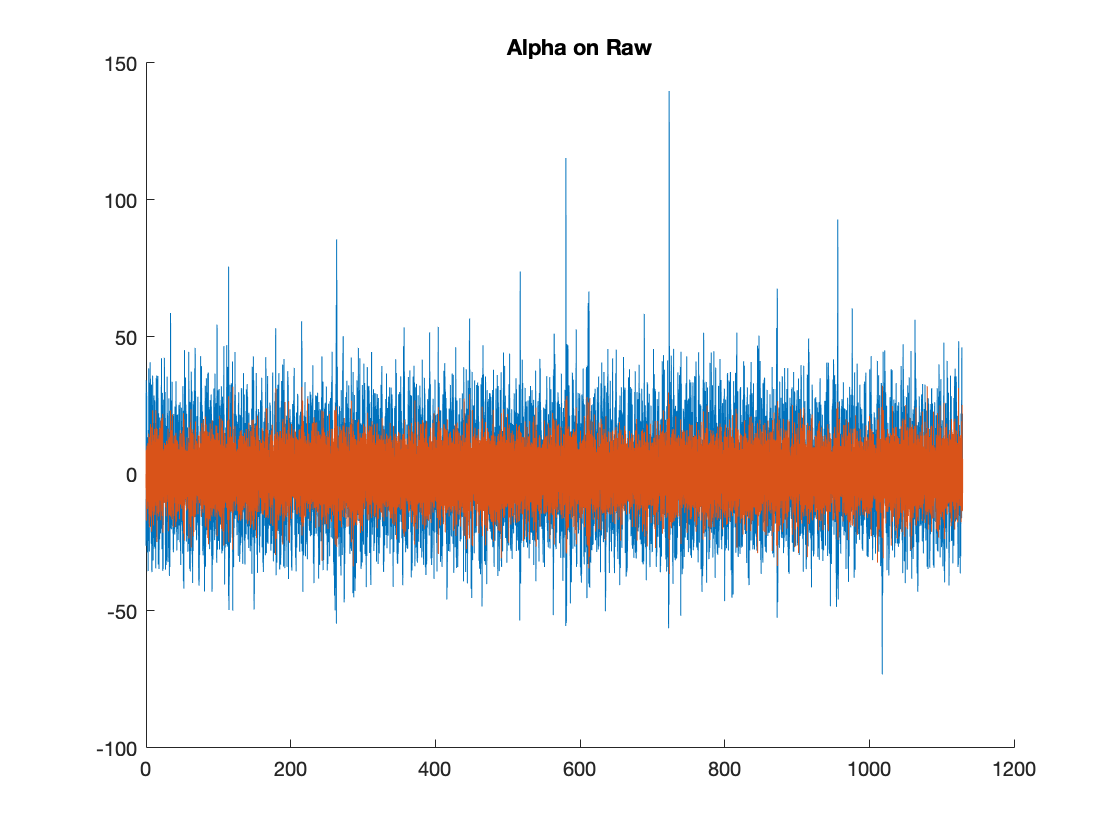

f_a = [1 10]; % alpha band
f_b = [18 22]; % beta band
N = 5; % filter order
[A1, A2] = butter(N, [f_a(1) f_a(2)]*2 /fs);
% [B1, B2] = butter(N, [f_b(1) f_b(2)]*2 /fs);
s_a = filter(A1, A2,signals); 
% s_b = filter(B1, B2,signals); 

rectSignal = s_a(:,:).^2; % signal power

figure % plot raw vs filtered signal
hold on
plot((1:length(signals(:,4)))./fs, signals(:,4))
plot((1:length(s_a))./fs, s_a(:,4))
title("Alpha on Raw")
hold off

## Grouping

errorIndex = []; % will contain trial number of every error trial
NEIndex = []; % will contain trial number of every no error trial
for i=1:length(event.type)
    if(event.type(i) == 1)
        errorIndex(end+1) = i; 
    else
        NEIndex(end+1) = i;
    end
end

## Sliding Window

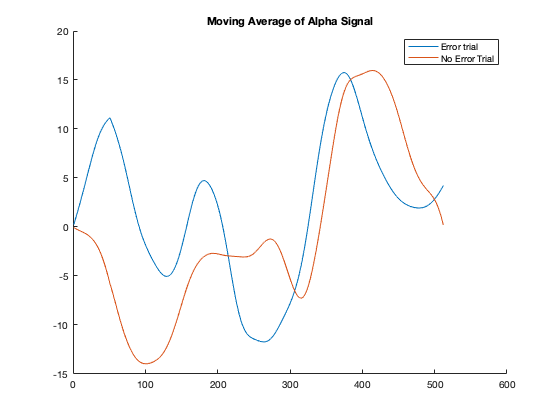

avg = .1; % average window .1 seconds 51 samples
testTrial = 5;
    
    
    
E_mavg = zeros(512,16); % moving avg of grand avg error signal
NE_mavg = zeros(512,16); % moving avgf of grand avg of no error signal
Etest = zeros(512,16); % moving avg of single error trial
NEtest = zeros(512,16);% moving avg of single no error trial
for c = 1:16
    E_mavg(:,c) = (filter(ones(1, round(avg*fs))/avg/fs, 1, GavgError(:,c)));
    NE_mavg(:,c) = (filter(ones(1, round(avg*fs))/avg/fs, 1, GavgNE(:,c)));    
    
        startSamp = event.position(errorIndex(testTrial))-beforeTrig*fs;
        endSamp = event.position(errorIndex(testTrial))+afterTrig*fs-1;
        
    Etest(:,c) = (filter(ones(1, round(avg*fs))/avg/fs, 1, s_a(startSamp:endSamp,c)));
    
        startSamp = event.position(NEIndex(testTrial))-beforeTrig*fs;
        endSamp = event.position(NEIndex(testTrial))+afterTrig*fs-1;
        
    NEtest(:,c) = (filter(ones(1, round(avg*fs))/avg/fs, 1, s_a(startSamp:endSamp,c)));
end


figure
hold on
% plot(E_mavg(:,3))
% plot(NE_mavg(:,3))
plot(Etest(:,3))
plot(NEtest(:,3))
hold off
legend("Error trial", "No Error Trial")
title("Moving Average of Alpha Signal")

% plot((1:length(GavgA))./fs, GavgA)

## Single trial

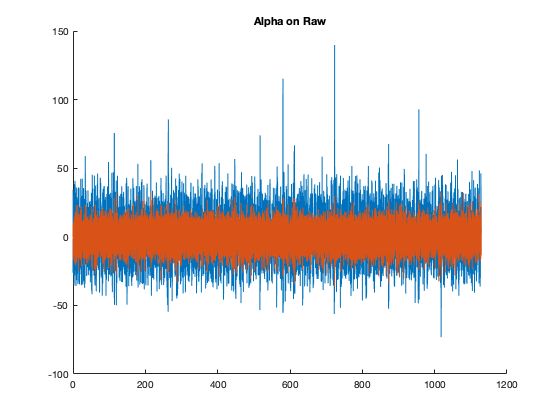

beforeTrig = 0; % seconds of signal to be recorded before start of trial
afterTrig = 1; % seconds of signal after trial start



figure

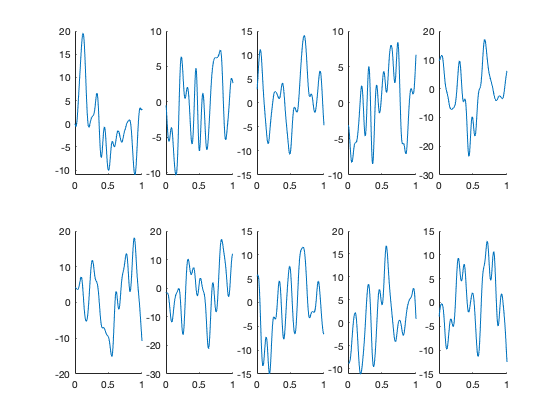

for(i=1:5)
    subplot(2,5,i)
    startSamp = event.position(errorIndex(i))-beforeTrig*fs; % gets the starting sample of indexed trial
    endSamp = event.position(errorIndex(i))+afterTrig*fs;  % gets the ending sample of indexed trial
    hold on
    % plot((1:length(signals(startSamp:endSamp,4)))./fs, signals(startSamp:endSamp,4))
    plot((1:length(s_a(startSamp:endSamp,4)))./fs, s_a(startSamp:endSamp,4))
%     title("Alpha on Raw")
    hold off
    subplot(2,5,i+5)
    startSamp = event.position(NEIndex(i))-beforeTrig*fs;
    endSamp = event.position(NEIndex(i))+afterTrig*fs;
    hold on
    % plot((1:length(signals(startSamp:endSamp,4)))./fs, signals(startSamp:endSamp,4))
    plot((1:length(s_a(startSamp:endSamp,4)))./fs, s_a(startSamp:endSamp,4))
%     title("Alpha on Raw")
    hold off
end

## Grand Average

GavgError = zeros(fs*(beforeTrig+afterTrig),16);
GavgNE = zeros(fs*(beforeTrig+afterTrig),16);
GavgRectError = zeros(fs*(beforeTrig+afterTrig),16);
GavgRectNE = zeros(fs*(beforeTrig+afterTrig),16);
for(c =1:16) % for every channel
    for(i=1:length(errorIndex)) % for every trial in error trial index array
        for(j = 1:length(GavgError)) % for length of trial (endsample - start sample)
            GavgError(j,c) = GavgError(j)+ s_a(event.position(errorIndex(i))-beforeTrig*fs+j, c);
            GavgRectError(j,c) = GavgRectError(j)+ rectSignal(event.position(errorIndex(i))-beforeTrig*fs+j, c);
        end 
    end
    for(i=1:length(NEIndex))
        for(j = 1:length(GavgNE))
            GavgNE(j,c) = GavgNE(j)+ s_a(event.position(NEIndex(i))-beforeTrig*fs+j, c);
            GavgRectNE(j,c) = GavgRectNE(j)+ rectSignal(event.position(NEIndex(i))-beforeTrig*fs+j, c);
        end 
    end
    GavgError(:,c) = GavgError(:,c)./length(errorIndex);
    GavgNE(:,c) = GavgNE(:,c)./length(NEIndex);
    GavgRectError(:,c) = GavgRectError(:,c)./length(errorIndex);
    GavgRectNE(:,c) = GavgRectNE(:,c)./length(NEIndex);
end
length(errorIndex)

ans = 94

length(NEIndex)

ans = 406

## plot Gavg

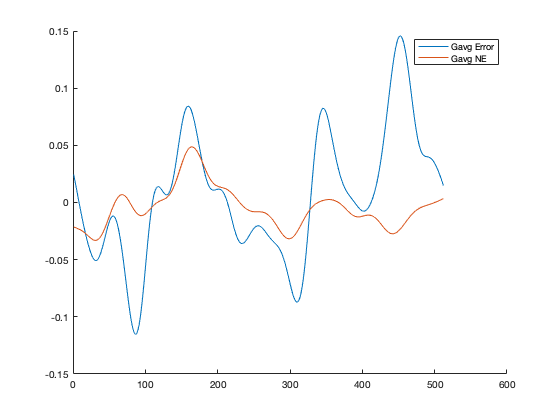

channel =3;
figure
hold on
plot(GavgError(:,channel))
% title("Grand Average of Error Signal")
% plot((1:length(GavgA))./fs, GavgA)

% subplot(2,1,2)
plot(GavgNE(:,channel))
% title("Grand Average of No Error Signal")
hold off
legend("Gavg Error", "Gavg NE")

## Power

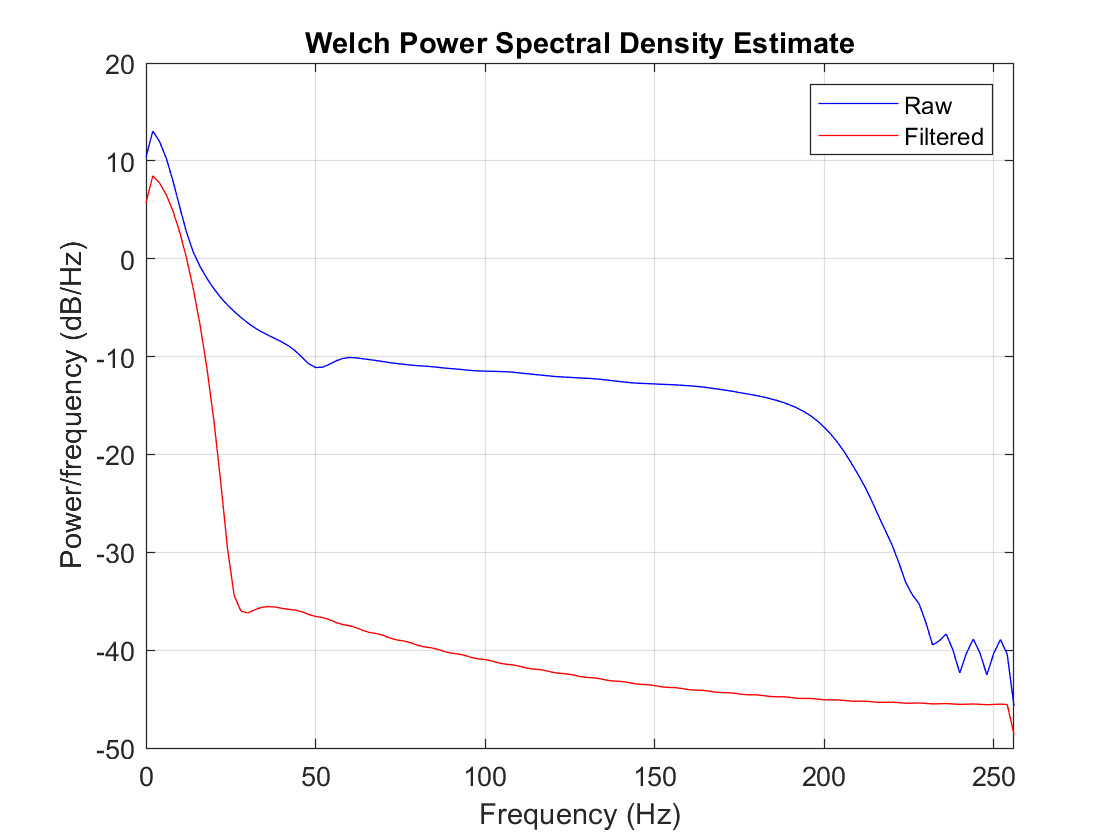

h = spectrum.welch; % creates the Welch spectrum estimator
% startSamp = event.position(errorIndex(10))-beforeTrig*fs;
% endSamp = event.position(errorIndex(10))+afterTrig*fs;
    
    
FCz = psd(h,signals(:, 4),'Fs',fs); 
Filtered = psd(h,s_a(:, 4),'Fs',fs); 
% noError=psd(h,s_a(startSamp:endSamp,4),'Fs',fs); 
% 
% startSamp = event.position(NEIndex(2))-beforeTrig*fs;
% endSamp = event.position(NEIndex(2))+afterTrig*fs;

% error = psd(h,s_a(startSamp:endSamp,4),'Fs',fs);
% figure('units','normalized','Position',[0.2,0.65,0.3,0.3])
figure
hold on
plot(FCz);
plot(Filtered);
% plot(noError);
% plot(error);
temp =get(gca);
temp.Children(1).Color = 'r'; %raw
temp.Children(2).Color = 'b'; %filtered
hold off
legend( 'Raw', 'Filtered');

## Spectrogram

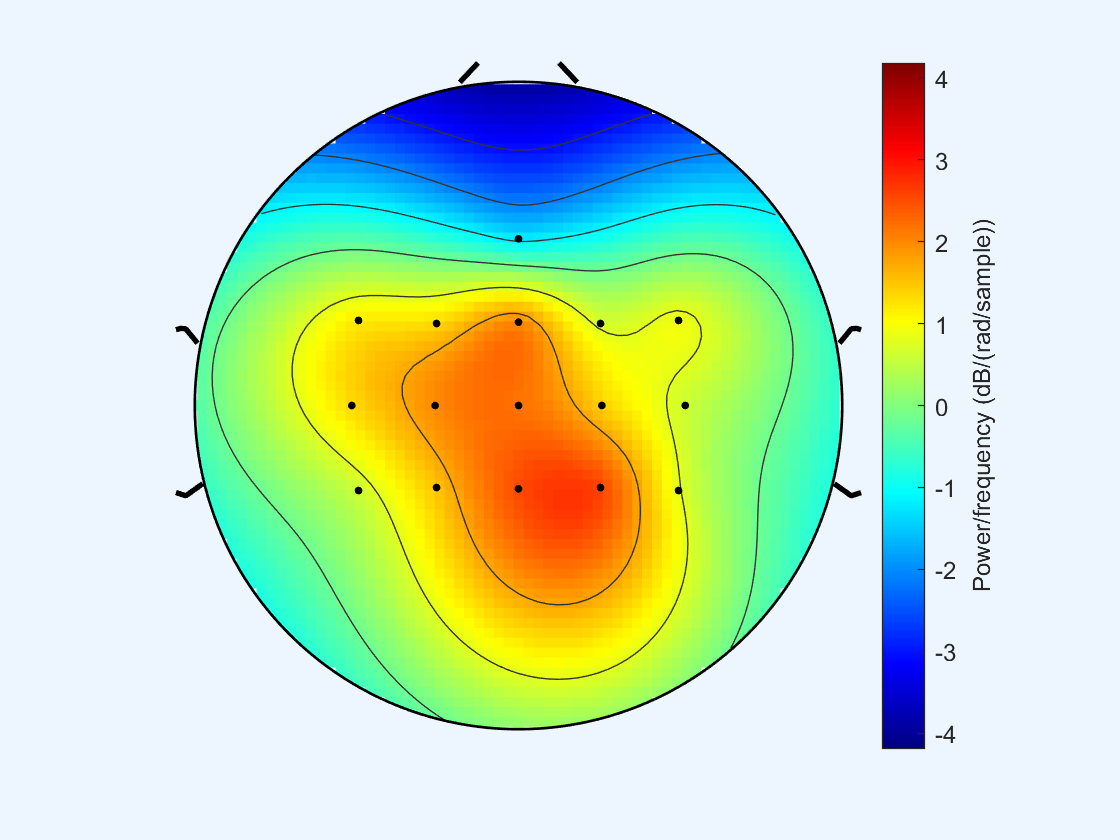

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [67×67 double]
           YData: [67×67 double]
           ZData: [67×67 double]
           CData: [67×67 double]

  Show all properties


% x = spectrogram(signals(:,4))
spectrogram(signals(:,4),4000,50,'yaxis')

topoplot((GavgRectError(87,:)-GavgRectNE(87,:)), chanlocs16)

topoplot(totalDiff, chanlocs16)

Unrecognized function or variable 'totalDiff'.

GavgRectDiff = GavgRectError(:,:)-GavgRectNE(:,:);
totalDiff = sum(GavgRectDiff(:,:))